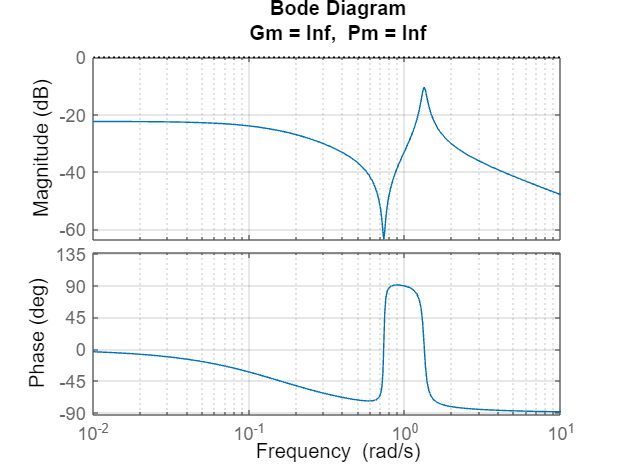

% Analytic Transfer function from Part 1
H = tf(K*[1 2*zeta1*wn1 wn1^2],[1 b+a c+(a*b) a*c]);

% Check the margins of H
margin(H)
grid on;

% [Gm_H, Pm_H, Wcg_H, Wcp_H] = margin(H)

% 1st approach

% Initial values for the compensator design
omega_z = 50;     % Zero of the compensator
omega_p = 1;    % Pole of the compensator
K_c = -0.1;        % Gain of the compensator
s = tf('s');
C = K_c * (s + omega_z) / (s + omega_p)

C =
 
  -0.1 s - 5
  ----------
    s + 1
 
Continuous-time transfer function.
Model Properties


L = C * H

L =
 
  -0.003966 s^3 - 0.1984 s^2 - 0.00635 s - 0.1063
  -----------------------------------------------
   s^4 + 1.25 s^3 + 2.029 s^2 + 2.059 s + 0.2797
 
Continuous-time transfer function.
Model Properties


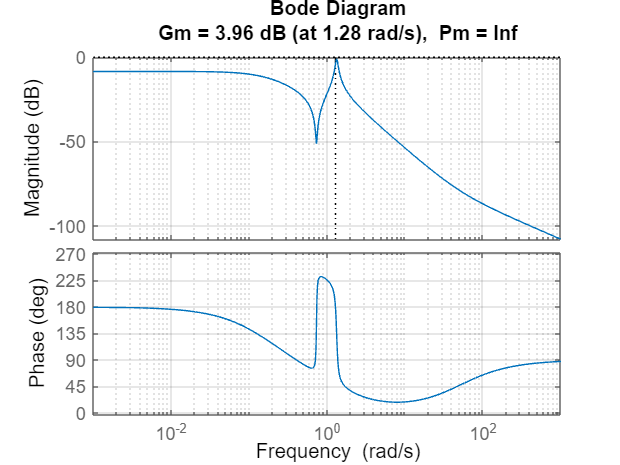


% 2nd approach
%alpha = 0.1; % for ~50 deg boost
%w_c = 2*pi*1; % crossover frequency at 1 Hz
%tau = 1/(w_c*sqrt(alpha));
%C_lead = tf([tau 1], [alpha*tau 1]);
%K_c = 10;
%C = K_c * C_lead; % Lead compensator
%L = C * H;

% Analyzing the margins
margin(L)
grid on;

[Gm, Pm, Wcg, Wcp] = margin(L)

Gm = 1.5782

Pm = Inf

Wcg = 1.2837

Wcp = NaN

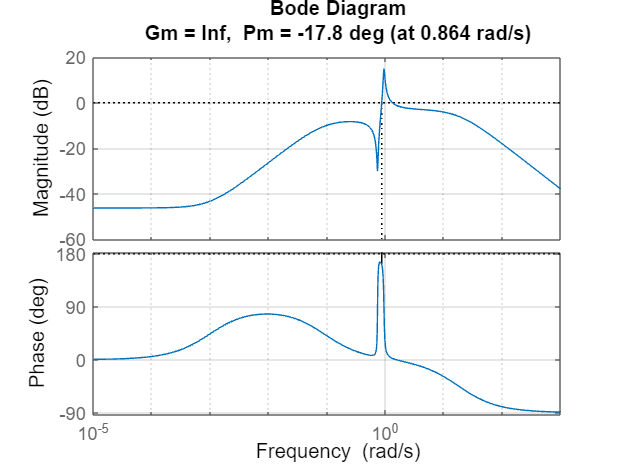

% Closed-loop system with compensator
T = feedback(L, 1);

% Check the new margins and bandwidth with the compensator
margin(T)
grid on;

[bw] = bandwidth(T);
disp(['Closed-Loop Bandwidth: ', num2str(bw), 'Hz']);

Closed-Loop Bandwidth: 3701.5104Hz
